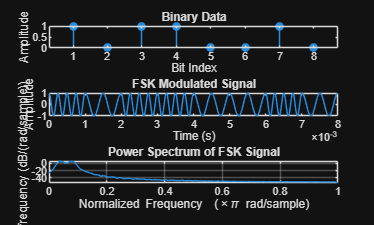

clc;
clear;
close all;

% Parameters
fs = 100000;              % Sampling frequency
Tb = 0.001;               % Bit duration
f1 = 4000;                % Frequency for bit 1
f0 = 2000;                % Frequency for bit 0

data = [1 0 1 1 0 0 1 0]; % Binary data

Ns = fs*Tb;               % Samples per bit
t = (0:Ns-1)/fs;          % Time vector for one bit

% Generate FSK signal
fsk_signal = [];

for i = 1:length(data)

    if data(i) == 1
        s = cos(2*pi*f1*t);
    else
        s = cos(2*pi*f0*t);
    end
    
    fsk_signal = [fsk_signal s];

end

% Total time axis
t_total = (0:length(fsk_signal)-1)/fs;

% Plot Signals
figure

subplot(3,1,1)
stem(data,'filled')
title('Binary Data')
xlabel('Bit Index')
ylabel('Amplitude')

subplot(3,1,2)
plot(t_total,fsk_signal)
title('FSK Modulated Signal')
xlabel('Time (s)')
ylabel('Amplitude')

subplot(3,1,3)
pwelch(fsk_signal)
title('Power Spectrum of FSK Signal')

received = fsk_signal;
demod = [];

for i = 1:length(data)

    segment = received((i-1)*Ns + 1 : i*Ns);

    ref1 = cos(2*pi*f1*t);
    ref0 = cos(2*pi*f0*t);

    corr1 = sum(segment .* ref1);
    corr0 = sum(segment .* ref0);

    if corr1 > corr0
        demod = [demod 1];
    else
        demod = [demod 0];
    end

end

disp('Original Data:')

Original Data:


disp(data)

     1     0     1     1     0     0     1     0




disp('Recovered Data:')

Recovered Data:


disp(demod)

     1     0     1     1     0     0     1     0

